pg_db = [-2 0 -1 -6 -9 -14];
tau_mus = [0 1.8 3.5 5.7 8.1 12.3];
tau = tau_mus*1e-6;
pg = 10.^(pg_db/10);

[~, tau_rms] = utils.rmsDelaySpread(pg, tau)

tau_rms = 2.3361e-06

1/tau_rms

ans = 4.2807e+05

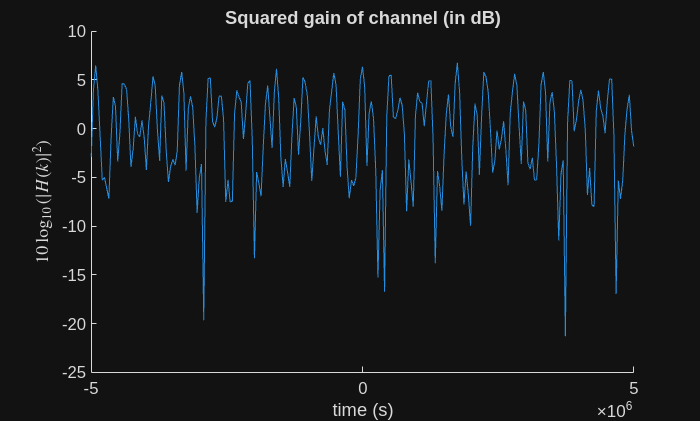

Nfft = 2048;
Ts = max(tau)*2/Nfft;
close all;
figure;
hold on;
for i=1:1
    [h, t] = utils.channelRealization(pg, tau, Ts, Nfft);
    H = fft(h);
    f = (-Nfft/2: Nfft/2-1)/(Nfft*Ts);
    H_dB = 10*log10(abs(H).^2);
    plot(f, H_dB)
end
title('Squared gain of channel (in dB)')
xlabel('time (s)')
ylabel('$10 \log_{10} \left( |H(k)|^2 \right)$', 'Interpreter', 'latex')
xlim([-10000000 10000000]/2)